# Import Steel data  S355

## Setting

Composition.element = ['C','Si','Mn','P','S','Cr','Ni','Mo','Cu','Al','Ti','V','B'];
Composition.content = [0.2300,0.0500,1.6000,0.0500,0.0500,0.0500,0.0750,0.0400,0.1000,0.0350,0.0100,0.0100,0.0003];
C =1;
Si=2;  
Mn=3;  
P=4;   
S=5;   
Cr=6;  
Ni=7;  
Mo=8;  
Cu=9;  
Al=10;  
Ti=11;  
V=12;   
B=13;   
CodeIDS = ['LIQ','fer+','aus+','euf+','fer-','euf-','MnS','zst','cur','SOL','Ae3','Acm','prf+','prc+','pea+','pea-','bai+','mar+'];
CtLIQ = 1;
ferPLUS = 2;
ausPLUS = 3;
eufPLUS = 4;
ferMINUS = 5;
                    eufMINUS = 6;
                    MnS = 7;
                    zst = 8;
                    cur = 9;
                    tSOL = 10;
                    Ae3 = 11;
                    Acm = 12;
                    prfPLUS = 13;
                    prcPLUS = 14;
                    peaPLUS = 15;
                    peaMINUS = 16;
                    baiPLUS = 17; 
                    marPLUS = 18;

Steel.Name = "S355";
Steel.Composition = zeros(10);
Steel.JmatPro.Temperature = zeros(500);
Steel.JmatPro.PhasesLIQUID = zeros(500);
Steel.JmatPro.PhasesAUSTENITE = zeros(500);
Steel.JmatPro.PhasesFERRITE = zeros(500);
Steel.JmatPro.PhasesMARTENSITE = zeros(500);
Steel.JmatPro.PhasesBAINITE = zeros(500);
Steel.JmatPro.Density = zeros(500);
Steel.JmatPro.Molarvolumecm3 = zeros(500);
Steel.JmatPro.Linearexpansion = zeros(500);
Steel.JmatPro.Averageexpansioncoeff10e61K = zeros(500);
Steel.JmatPro.ThermalconductivityWmK = zeros(500);
Steel.JmatPro.Electricalresistivity10e6OhmmTOTAL = zeros(500);
Steel.JmatPro.Electricalconductivity10e61OhmmTOTAL = zeros(500);
Steel.JmatPro.YoungsmodulusGPaTOTAL = zeros(500);
Steel.JmatPro.BulkmodulusGPaTOTAL = zeros(500);
Steel.JmatPro.ShearmodulusGPaTOTAL = zeros(500);
Steel.JmatPro.PoissonsratioTOTAL = zeros(500);
Steel.JmatPro.LiquidviscositymPas = zeros(500);
Steel.JmatPro.TotalviscositymPas = zeros(500);
Steel.JmatPro.YieldStressMPaTOTAL = zeros(500);
Steel.JmatPro.TensileStressMPaTOTAL = zeros(500);
Steel.JmatPro.HardnessHRCTOTAL = zeros(500);
Steel.JmatPro.EnthalpyJgTOTAL = zeros(500);
Steel.JmatPro.SpecificheatJgKTOTAL = zeros(500);
Steel.JmatPro.LatentheatJgFERRITE = zeros(500);
Steel.JmatPro.LatentheatJgBAINITE_PEARLITE10Cs = zeros(500);
Steel.JmatPro.LatentheatJgMARTENSITE= zeros(500);
Steel.JmatPro.LatentheatJgSOLID = zeros(500);
Steel.JmatPro.TIMEsCooling = zeros(500);
Steel.IDS.Code = zeros(18);
Steel.IDS.Temperature = zeros(500);
Steel.IDS.Entalphy = zeros(500);
Steel.IDS.Capacity = zeros(500);
Steel.IDS.Conductivity = zeros(500);
Steel.IDS.Density = zeros(500);
Steel.IDS.Contracte = zeros(500);
Steel.IDS.Alfa = zeros(500);
Steel.IDS.Viscosity = zeros(500);

opts = delimitedTextImportOptions("NumVariables", 29);

% Specify range and delimiter
opts.DataLines = [2, inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Temperature", "PhasesLIQUID", "PhasesAUSTENITE", "PhasesFERRITE", "PhasesMARTENSITE", "PhasesBAINITE", "Densitygcm3TOTAL", "Molarvolumecm3TOTAL", "Linearexpansion", "Averageexpansioncoeff10e61K", "ThermalconductivityWmKTOTAL", "Electricalresistivity10e6OhmmTOTAL", "Electricalconductivity10e61OhmmTOTAL", "YoungsmodulusGPaTOTAL", "BulkmodulusGPaTOTAL", "ShearmodulusGPaTOTAL", "PoissonsratioTOTAL", "LiquidviscositymPas", "TotalviscositymPas", "YieldStressMPaTOTAL", "TensileStressMPaTOTAL", "HardnessHRCTOTAL", "EnthalpyJgTOTAL", "SpecificheatJgKTOTAL", "LatentheatJgFERRITE", "LatentheatJgBAINITE_PEARLITE", "LatentheatJgMARTENSITE", "LatentheatJgSOLID", "TIMEsCooling"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Temperature", "PhasesLIQUID", "PhasesAUSTENITE", "PhasesFERRITE", "PhasesMARTENSITE", "PhasesBAINITE", "Densitygcm3TOTAL", "Molarvolumecm3TOTAL", "Linearexpansion", "Averageexpansioncoeff10e61K", "ThermalconductivityWmKTOTAL", "Electricalresistivity10e6OhmmTOTAL", "Electricalconductivity10e61OhmmTOTAL", "YoungsmodulusGPaTOTAL", "BulkmodulusGPaTOTAL", "ShearmodulusGPaTOTAL", "PoissonsratioTOTAL", "LiquidviscositymPas", "TotalviscositymPas", "YieldStressMPaTOTAL", "TensileStressMPaTOTAL", "HardnessHRCTOTAL", "EnthalpyJgTOTAL", "SpecificheatJgKTOTAL", "LatentheatJgFERRITE", "LatentheatJgBAINITE_PEARLITE", "LatentheatJgMARTENSITE", "LatentheatJgSOLID", "TIMEsCooling"], "FillValue", 0);

% Import the data
tbl = readtable("C:\Users\stetina\MATLAB Drive\Caster\S355.dat", opts);

## Convert to output type

Steel.JmatPro.Temperature = tbl.Temperature;
Steel.JmatPro.PhasesLIQUID = tbl.PhasesLIQUID;
Steel.JmatPro.PhasesAUSTENITE = tbl.PhasesAUSTENITE;
Steel.JmatPro.PhasesFERRITE = tbl.PhasesFERRITE;
Steel.JmatPro.PhasesMARTENSITE = tbl.PhasesMARTENSITE;
Steel.JmatPro.PhasesBAINITE = tbl.PhasesBAINITE;
Steel.JmatPro.Density = tbl.Densitygcm3TOTAL*1000;
Steel.JmatPro.Molarvolumecm3 = tbl.Molarvolumecm3TOTAL;
Steel.JmatPro.Linearexpansion = tbl.Linearexpansion;
Steel.JmatPro.Averageexpansioncoeff10e61K = tbl.Averageexpansioncoeff10e61K;
Steel.JmatPro.ThermalconductivityWmK = tbl.ThermalconductivityWmKTOTAL;
Steel.JmatPro.Electricalresistivity10e6OhmmTOTAL = tbl.Electricalresistivity10e6OhmmTOTAL;
Steel.JmatPro.Electricalconductivity10e61OhmmTOTAL = tbl.Electricalconductivity10e61OhmmTOTAL;
Steel.JmatPro.YoungsmodulusGPaTOTAL = tbl.YoungsmodulusGPaTOTAL;
Steel.JmatPro.BulkmodulusGPaTOTAL = tbl.BulkmodulusGPaTOTAL;
Steel.JmatPro.ShearmodulusGPaTOTAL = tbl.ShearmodulusGPaTOTAL;
Steel.JmatPro.PoissonsratioTOTAL = tbl.PoissonsratioTOTAL;
Steel.JmatPro.LiquidviscositymPas = tbl.LiquidviscositymPas;
Steel.JmatPro.TotalviscositymPas = tbl.TotalviscositymPas;
Steel.JmatPro.YieldStressMPaTOTAL = tbl.YieldStressMPaTOTAL;
Steel.JmatPro.TensileStressMPaTOTAL = tbl.TensileStressMPaTOTAL;
Steel.JmatPro.HardnessHRCTOTAL = tbl.HardnessHRCTOTAL;
Steel.JmatPro.EnthalpyJgTOTAL = tbl.EnthalpyJgTOTAL;
Steel.JmatPro.SpecificheatJgKTOTAL = tbl.SpecificheatJgKTOTAL;
Steel.JmatPro.LatentheatJgFERRITE = tbl.LatentheatJgFERRITE;
Steel.JmatPro.LatentheatJgBAINITE_PEARLITE10Cs = tbl.LatentheatJgBAINITE_PEARLITE;
Steel.JmatPro.LatentheatJgMARTENSITE= tbl.LatentheatJgMARTENSITE;
Steel.JmatPro.LatentheatJgSOLID = tbl.LatentheatJgSOLID;
Steel.JmatPro.TIMEsCooling = tbl.TIMEsCooling;
clear opts tbl

## Read IDS data

nNumColumns = 8;   
fileName = "C:\Users\stetina\MATLAB Drive\Caster\S355.UM";
                        
interpMethod = 'linear'; % asi nejlepsi volba, 'spline' se 'vlni' v mistech fazove zmeny
            
f = fopen(fileName, 'r');
if (f == -1)
   error('The given file does not exist.');                
end
%if (fileName(length(fileName)) ~= 'M' || fileName(length(fileName) - 1) ~= 'U')
%   error('A wrong type of file! The type .UM is needed!');
%end
  
line = fgets(f);
lineToASCII = unicode2native(line);
            
i = 0;
            
while (line ~= -1)
  lineToASCII = unicode2native(line);
  if ((line(1) ~= '#') && (lineToASCII(1) ~= 13) && (lineToASCII(2) ~= 10)) % matlab neumi pouzit ceckovske '\n', proto takto tezkopadne kontrola konce radku
  i = i + 1;  
% originalni data: === T(C) === H(J/g)  === c(J/gK) === lambda(W/mK) === rho(kg/m3) === Cont(%) === alfa(1/K) === V(mPas) === udalost
  s = textscan(line, '%f %f %f %f %f %f %f %f %s');
  for j = 1:nNumColumns
    temp(i, j) = s{j};
  end
                    
% rozpoznani 'udalosti' z posledniho sloupce
  event = char(s{9});
  multiplicity = 1;
  separatorPositions(1) = 0;
  for j = 1:length(event)
    if (event(j) == '_')
      multiplicity = multiplicity + 1;
      separatorPositions(multiplicity) = j;
    end
  end
  separatorPositions(multiplicity + 1) = length(event) + 1;
                    
  for j = 1:multiplicity
     ev = event(separatorPositions(j) + 1 : separatorPositions(j + 1) - 1);
     if (~strcmp(ev, '*'))
       recognizeEvent(ev, temp, i);
     end
   end
                 
   % prepoctena data: === T(C) === H(J/m3) === c(J/kgK) === lambda(W/mK) === rho(kg/m3) === Cont(%) === alfa(1/K) === V(mPas)
   temp(i, 2) = temp(i, 2) * 1000 * temp(i, 5); % prevod entalpie
   temp(i, 3) = temp(i, 3) * 1000; % prevod merne tepelne kapacity                    
   end
   line = fgets(f);      
   end
       
   fclose(f);

Steel.IDS.Temperature = temp(:,1);   
Steel.IDS.Entalphy = temp(:,2);
Steel.IDS.Capacity = temp(:,3);
Steel.IDS.Conductivity = temp(:,4);
Steel.IDS.Density = temp(:,5);
Steel.IDS.Contracte = temp(:,6);
Steel.IDS.Alfa = temp(:,7);
Steel.IDS.Viscosity = temp(:,8);

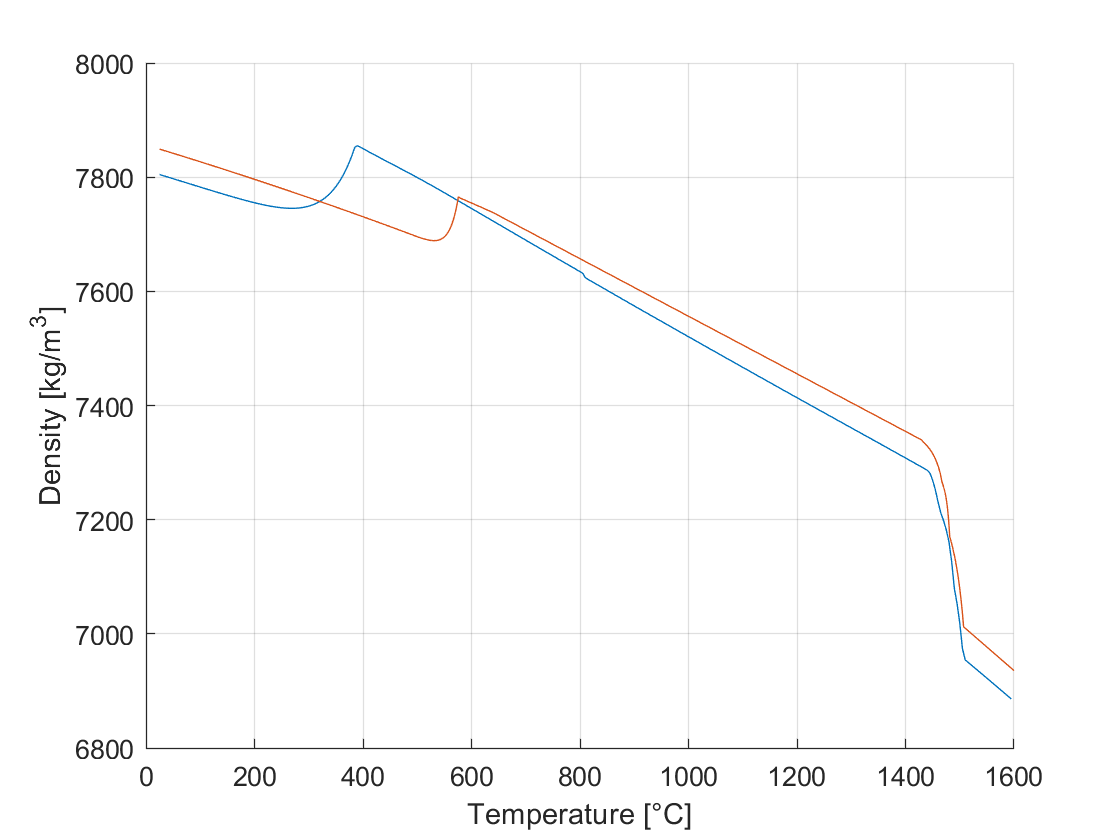

xlabel('Temperature [°C]');
xlim('auto');
ylim('auto');
grid on;
xlabel('Temperature [°C]');
ylabel('Density [kg/m^3]');
hold on;
plot(Steel.JmatPro.Temperature,Steel.JmatPro.Density);
plot(Steel.IDS.Temperature,Steel.IDS.Density); 
hold off;

% local function
function [] = recognizeEvent(event, temp, i)
            switch event
                case 'LIQ'
                    tLIQ = temp(i, 1);
                case 'fer+'
                    ferPLUS = temp(i, 1);
                case 'aus+'
                    ausPLUS = temp(i, 1);
                case 'euf+'
                    eufPLUS = temp(i, 1);
                case 'fer-'
                    ferMINUS = temp(i, 1);
                case 'euf-'
                    eufMINUS = temp(i, 1);
                case 'MnS'
                    MnS = temp(i, 1);
                case 'zst'
                    zst = temp(i, 1);
                case 'cur'
                    cur = temp(i, 1);
                case 'SOL'
                    tSOL = temp(i, 1);
                case 'Ae3'
                    Ae3 = temp(i, 1);
                case 'Acm'
                    Acm = temp(i, 1);
                case 'prf+'
                    prfPLUS = temp(i, 1);
                case 'prc+'
                    prcPLUS = temp(i, 1);
                case 'pea+'
                	peaPLUS = temp(i, 1);
                case 'pea-'
                    peaMINUS = temp(i, 1);
                case 'bai+'
                    baiPLUS = temp(i, 1);
                case 'mar+'
                    marPLUS = temp(i, 1);
            end          
        end